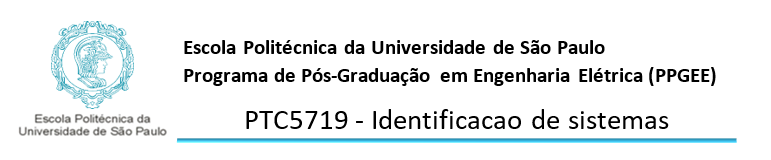

# Elton Inacio Alves Junior - 12501745

# LISTA 2

Considere o mesmo processo da 1ª lista de exercícios

**A.** Considere o processo afetado por perturbações de baixa intensidade. Para estimar o  período de amostragem  Ts a ser usado, considere$\textrm{Ts}=\;\tau /10$  e $\textrm{Ts}\;=\;\textrm{ts}/10$. Selecione  aquele que, em sua opinião, seja o mais adequado para o processo em questão.  Justifique a sua resposta. Daqui para a frente considere o intervalo de amostragem  Ts aqui obtido.

% O período de amostragem (T) pode ser dado através de duas equações:
% Sendo:
tau = 10;
t_s = 48;

% Temos:
T1 = tau/10   % ou

T1 = 1

T2 = t_s/10

T2 = 4.8000

% Neste caso podemos utilizar o menor valor para termos mais precisão, portanto:
T1

T1 = 1

clc;clear;close all;

% Variáveis...
    grafico=0;
    linha=1;
    
    %variâncias
    baixa=0.001;
    
    k=2;
    tau=10;
    Kpert1=1;
    TAUpert1=5;
    theta=3;
    Kpert2=2;
    

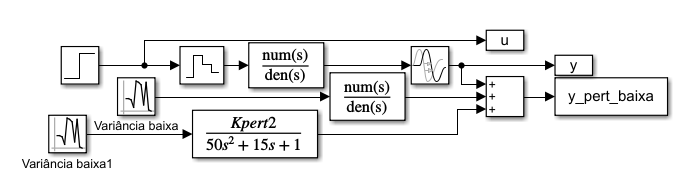

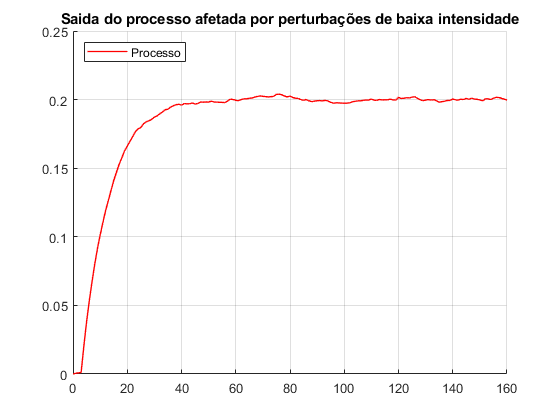

% Rodando simulação do Simulink
    Tsim = 160;
    sim('Lista_2_ex_a');

% Plotando o gráfico
    grafico = grafico + 1;
    figure(grafico);
    grid;
    hold on;
    plot(t,y_pert_baixa,'red','linewidth',linha);     % Contínuo
    
    title({'Saida do processo afetada por perturbações de baixa intensidade'});
    legend('Processo','location','northwest');

**B.** Classifique o modelo linear do processo (incluindo as perturbações 1 v e  2 v ) segundo as  estruturas tradicionalmente empregadas na área de Identificação de Sistemas (ARX,  ARMAX, OE, BJ etc). Defina as ordens do modelo.

podemos classificar o modelo como BJ pois todos os polinômios têm coeficientes diferentes:

                              
$$y{\left(t\right)}=\frac{B{\left(q\right)}}{F{\left(q\right)}}u{\left(t\right)}+\frac{C\left(q\right)}{D{\left(q\right)}}\varepsilon \left(t\right)$$


clc;clear;close all;

% Variáveis...
    grafico=0;
    linha=1;
    
    %variâncias
    baixa=0.001;
    alta=0.1;
    
    k=2;
    tau=10;
    Kpert1=1;
    TAUpert1=5;
    theta=3;
    Kpert2=2;

% Sistema Contínuo
    Gcont=tf(k,[tau 1],'inputdelay',theta);
    Hcont=tf(Kpert1,[TAUpert1 1]);

% Convertendo para discreto
    Gdisc=c2d(Gcont,1,'zoh');
    Hdisc=c2d(Hcont,1,'zoh');
    

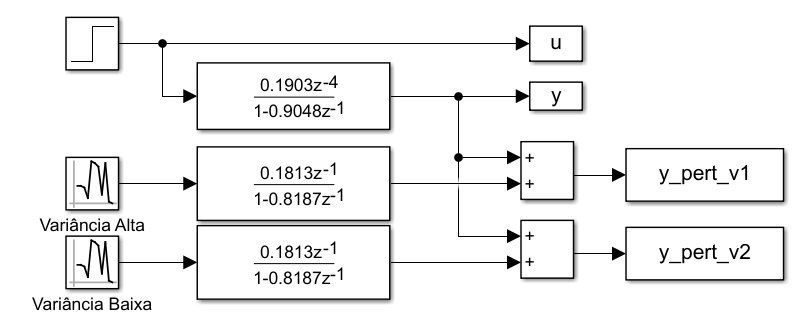

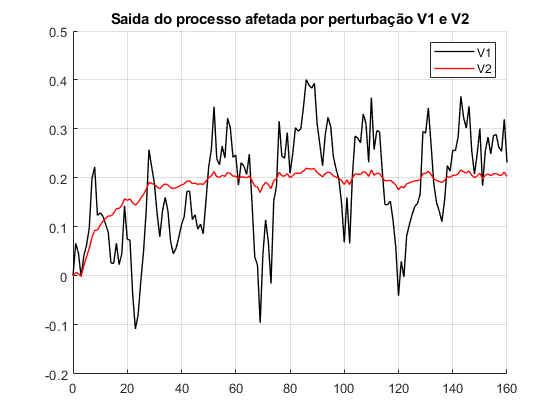

% Rodando simulação do Simulink
    Tsim = 160;
    sim('Lista_2_ex_b');

% Plotando o gráfico
    grafico = grafico + 1;
    figure(grafico);
    grid;
    hold on;
    %plot(t,y_pert_v1,'red','linewidth',linha);     % Contínuo
    
    plot(t,y_pert_v1,'black','linewidth',linha);     % Contínuo
    plot(t,y_pert_v2,'red','linewidth',linha);     % Contínuo
    
    title({'Saida do processo afetada por perturbação V1 e V2'});
    legend('V1','V2');

**C.** Simule o processo com níveis baixo e alto de perturbação por 600 segundos usando,  como entrada u, um degrau com amplitude de 0,1 aplicado em t=275 s. Registre três  saídas do processo: a saída y limpa (sem perturbações nem ruído de medição) e as saídas baixa y e  alta y , afetadas, respectivamente, pelas perturbações  1 v e  2 v de baixa e  alta intensidades e por ruído de medição

    clc;clear;close all;

% Variáveis...
    grafico=0;
    linha=1;
    
   %variâncias
    baixa=0.001;
    alta=0.1;
    vari=1e-6;
    
    k=2;
    tau=10;
    Kpert1=1;
    TAUpert1=5;
    theta=3;
    Kpert2=2;
    TAUpert21=5;
    TAUpert22=10;

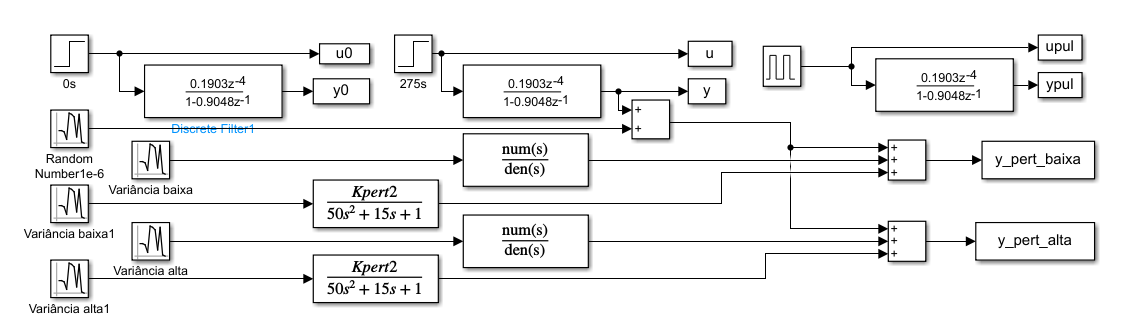

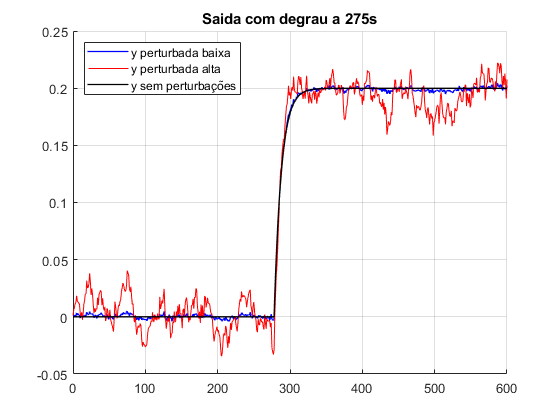

% Rodando simulação do Simulink
    Tsim = 600;
    sim('Lista_2_ex_c');

    
% Plotando o gráfico
    grafico = grafico + 1;
    figure(grafico);
    grid;
    hold on;
    plot(t,y_pert_baixa,'blue','linewidth',linha);     % Contínuo
    plot(t,y_pert_alta,'red','linewidth',0.5);     % Contínuo
    plot(t,y,'black','linewidth',linha);     % Contínuo
    
    title({'Saida com degrau a 275s'});
    legend('y perturbada baixa','y perturbada alta', ...
        'y sem perturbações','location','northwest');

**D.** Usando o toolbox de identificação do MATLAB e os dados medidos no item “c”, estime  modelos para a saída limpa y, utilizando estruturas FIR, ARX, ARMAX, OE e BJ, com as  ordens corretas dos modelos discretizados e com uma única entrada u. Considere para  o modelo FIR que a ordem nb=ts_aprox (tempo de acomodação aproximado extraído do  item “f” da 1ª lista de exercícios). Apresente os modelos obtidos e compare os valores  estimados dos parâmetros com seus valores reais dados pela função de transferência  discreta do processo. Compare a resposta dos modelos obtidos com excitação do tipo  degrau de amplitude 0,1 com a resposta limpa do processo a esse mesmo degrau.  Aplique o comando “predict” para realizar predições infinitos passos à frente e compare  a qualidade dos modelos obtidos usando o comando “compare” do Matlab, considerando  horizonte de predição infinito (pior caso possível) e apresentando o índice fit obtido para  cada modelo. Lembre-se que este caso, isento de perturbações e ruído de medição,  corresponde a uma situação teórica, possível apenas em simuladores. Comente os  resultados obtidos pelos modelos gerados neste caso hipotético. 

**E.** Apresente e compare o ganho estacionário dos modelos obtidos no item “d” com o  ganho estacionário do processo. Teça comentários. 

Para a função de transferência discreta do processo:


$$G{\left(z\right)}=\frac{0,1903\ldotp z^{-4} }{0,9048{\ldotp z}^{-1} }$$


Temos as estruturas abaixo com os modelos estimados sem perturbação, podemos verificar que os coeficientes são iguais aos do sistema discreto do processo.

**ARX:          **$y{\left(t\right)}=\frac{B{\left(q\right)}}{A{\left(q\right)}}u{\left(t\right)}+\frac{1}{A{\left(q\right)}}\varepsilon \left(t\right)\Rightarrow y{\left(t\right)}=\frac{0,1903\ldotp q^{-4} }{1-0,9048\ldotp q^{-1} }u{\left(t\right)}$ 

**ARMAX:    **$y{\left(t\right)}=\frac{B{\left(q\right)}}{A{\left(q\right)}}u{\left(t\right)}+\frac{C\left(q\right)}{A{\left(q\right)}}\varepsilon \left(t\right)\Rightarrow y{\left(t\right)}=\frac{0,1903\ldotp q^{-4} }{1-0,9048\ldotp q^{-1} }u{\left(t\right)}$

**OE:            **$y{\left(t\right)}=\frac{B{\left(q\right)}}{F{\left(q\right)}}u{\left(t\right)}+\varepsilon \left(t\right)\;\Rightarrow y{\left(t\right)}=\frac{0,1903\ldotp q^{-4} }{1-0,9048\ldotp q^{-1} }u{\left(t\right)}$

**BJ:             **$y{\left(t\right)}=\frac{B{\left(q\right)}}{F{\left(q\right)}}u{\left(t\right)}+\frac{C\left(q\right)}{D{\left(q\right)}}\varepsilon \left(t\right)\Rightarrow y{\left(t\right)}=\frac{0,1903\ldotp q^{-4} }{1-0,9048\ldotp q^{-1} }u{\left(t\right)}$

    clc;clear;close all; warning off;
    
% Variáveis...
    grafico=0;
    linha=1;
    
   %variâncias
    baixa=0.001;
    alta=0.1;
    vari=1e-6;
    
    k=2;
    tau=10;
    Kpert1=1;
    TAUpert1=5;
    theta=3;
    Kpert2=2;
    TAUpert21=5;
    TAUpert22=10;
    
    
% Rodando simulação do Simulink
    Tsim = 600;
    sim('Lista_2_ex_c');

% Sistema Contínuo
    Sisc=tf(k,[tau 1],'inputdelay',theta);

% Convertendo para discreto
    Sisd=c2d(Sisc,1,'zoh');

% Sistemas    
    data = iddata(y,u,1);
    datapert = iddata(y_pert_baixa,u,1);
    data0 = iddata(y0,u0,1);
    

Para o modelo FIR, utilizando a ordem nb=60, temos o polinômio B a seguir:

    fir = arx(data,[0 60 4]);

`fir =`

`Discrete-time FIR model: y(t) =  B(z)u(t) + e(t)                                                                                                                    `

`  B(z) = 0.1903 z^-4 + 0.1722 z^-5 + 0.1558 z^-6 + 0.141 z^-7 + 0.1275 z^-8 + 0.1154 z^-9 + 0.1044 z^-10 + 0.09447 z^-11 + 0.08548 z^-12 + 0.07734 z^-13            `

`          + 0.06998 z^-14 + 0.06332 z^-15 + 0.05729 z^-16 + 0.05183 z^-17 + 0.0469 z^-18 + 0.04244 z^-19 + 0.0384 z^-20 + 0.03474 z^-21 + 0.03143 z^-22             `

`          + 0.02844 z^-23 + 0.02573 z^-24 + 0.02328 z^-25 + 0.02107 z^-26 + 0.01906 z^-27 + 0.01725 z^-28 + 0.0156 z^-29 + 0.01412 z^-30 + 0.01277 z^-31            `

`          + 0.01156 z^-32 + 0.01046 z^-33 + 0.009463 z^-34 + 0.008562 z^-35 + 0.007747 z^-36 + 0.007009 z^-37 + 0.006342 z^-38 + 0.005738 z^-39 + 0.005192 z^-40    `

`          + 0.004698 z^-41 + 0.00425 z^-42 + 0.003846 z^-43 + 0.00348 z^-44 + 0.003148 z^-45 + 0.002849 z^-46 + 0.002578 z^-47 + 0.002332 z^-48 + 0.00211 z^-49     `

`          + 0.001909 z^-50 + 0.001727 z^-51 + 0.001563 z^-52 + 0.001414 z^-53 + 0.00128 z^-54 + 0.001158 z^-55 + 0.001048 z^-56 + 0.0009478 z^-57 + 0.0008576 z^-58 `

`                                                                        + 0.0007759 z^-59 + 0.0007021 z^-60 + 0.0006352 z^-61 + 0.0005748 z^-62 + 0.005265 z^-63    `

`Sample time: 1 seconds`

`Parameterization:`

`   Polynomial orders:   nb=60   nk=4`

`   Number of free coefficients: 60`

`   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.`

`Status:                                        `

`Estimated using ARX on time domain data "data".`

`Fit to estimation data: 99.95%                 `

`FPE: 3.104e-09, MSE: 2.071e-09                 `

    arx = arx(data,[1 1 4]);
    armax = armax(data,[1 1 0 4]);
    oe = oe(data,[1 1 4]);
    bj = bj(data,[1 0 0 1 4]);
    
    %fir = impulseest(data,60,4);
    
% Predições    
    pre_arx = predict(arx,data,inf);
    pre_armax = predict(armax,data,inf);
    pre_oe = predict(oe,data,inf);
    pre_bj = predict(bj,data,inf);
    pre_fir = predict(fir,data,inf);


Comparando os modelos obtidos temos todos os modelos iguais (somente o modelo FIR possui uma pequena diferença de 0,05%:

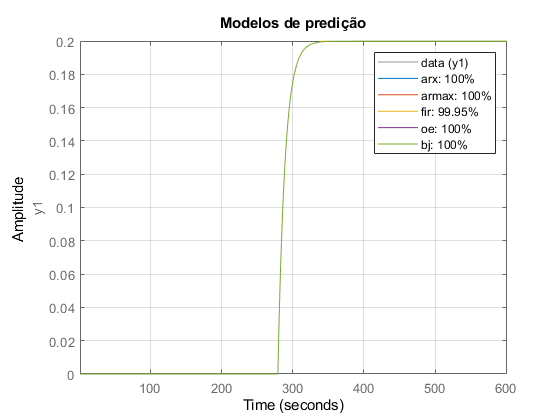

    compare(data,arx,armax,fir,oe,bj,Inf); grid on; title({'Modelos de predição'});

Gerando os modelos de predição temos as saída iguais a do processo:

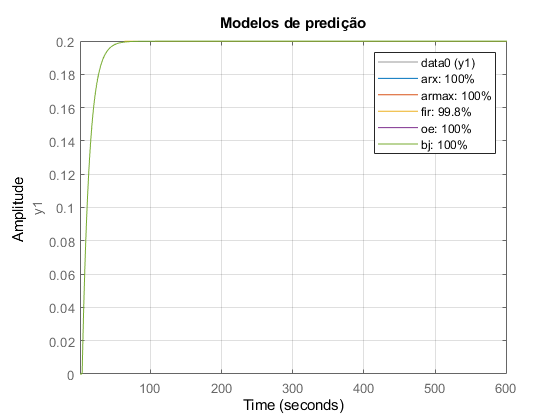

    compare(data0,arx,armax,fir,oe,bj,Inf); grid on; title({'Modelos de predição'});

Comparando com o sinal perturbado para simular uma validação feita na prática,  temos os modelos bem fieis a saída do processo:

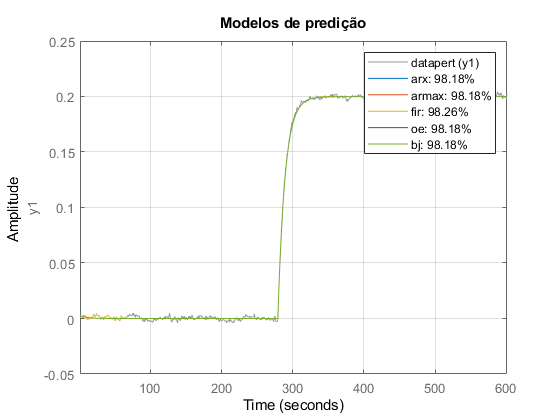

    compare(datapert,arx,armax,fir,oe,bj,Inf); grid on; title({'Modelos de predição'});

**F.** Apresente em um gráfico e compare os coeficientes gerados pelo modelo FIR do item  “d” com a resposta impulsiva do processo limpo ao impulso unitário. Teça comentários. 

    clc;clear;close all;
warning off;
% Variáveis...
    grafico=0;
    linha=1;
    
   %variâncias
    baixa=0.001;
    alta=0.1;
    vari=1e-6;
    
    k=2;
    tau=10;
    Kpert1=1;
    TAUpert1=5;
    theta=3;
    Kpert2=2;
    TAUpert21=5;
    TAUpert22=10;
    

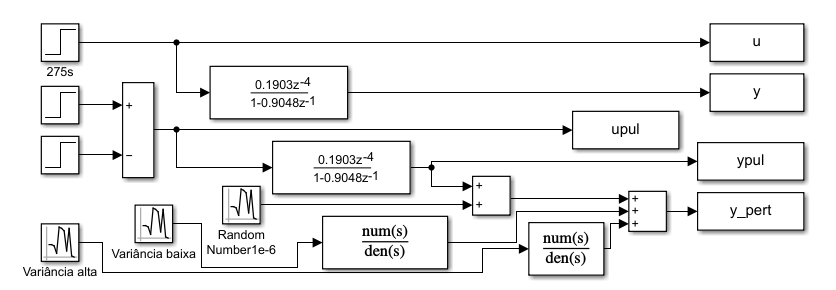

    
% Rodando simulação do Simulink
    Tsim = 600;
    sim('Lista_2_ex_f');
    
    data = iddata(y,u,1);
    datapul = iddata(ypul,upul,1);
    

O coeficiente gerado pelo modelo FIR no exercício "d" foi

    fir = arx(data,[0 60 4]);

`fir =`

`Discrete-time FIR model: y(t) =  B(z)u(t) + e(t)                                                                                                                    `

`  B(z) = 0.1903 z^-4 + 0.1722 z^-5 + 0.1558 z^-6 + 0.141 z^-7 + 0.1275 z^-8 + 0.1154 z^-9 + 0.1044 z^-10 + 0.09447 z^-11 + 0.08548 z^-12 + 0.07734 z^-13            `

`          + 0.06998 z^-14 + 0.06332 z^-15 + 0.05729 z^-16 + 0.05183 z^-17 + 0.0469 z^-18 + 0.04244 z^-19 + 0.0384 z^-20 + 0.03474 z^-21 + 0.03143 z^-22             `

`          + 0.02844 z^-23 + 0.02573 z^-24 + 0.02328 z^-25 + 0.02107 z^-26 + 0.01906 z^-27 + 0.01725 z^-28 + 0.0156 z^-29 + 0.01412 z^-30 + 0.01277 z^-31            `

`          + 0.01156 z^-32 + 0.01046 z^-33 + 0.009463 z^-34 + 0.008562 z^-35 + 0.007747 z^-36 + 0.007009 z^-37 + 0.006342 z^-38 + 0.005738 z^-39 + 0.005192 z^-40    `

`          + 0.004698 z^-41 + 0.00425 z^-42 + 0.003846 z^-43 + 0.00348 z^-44 + 0.003148 z^-45 + 0.002849 z^-46 + 0.002578 z^-47 + 0.002332 z^-48 + 0.00211 z^-49     `

`          + 0.001909 z^-50 + 0.001727 z^-51 + 0.001563 z^-52 + 0.001414 z^-53 + 0.00128 z^-54 + 0.001158 z^-55 + 0.001048 z^-56 + 0.0009478 z^-57 + 0.0008576 z^-58 `

`                                                                        + 0.0007759 z^-59 + 0.0007021 z^-60 + 0.0006352 z^-61 + 0.0005748 z^-62 + 0.005265 z^-63    `

`Sample time: 1 seconds`

`Parameterization:`

`   Polynomial orders:   nb=60   nk=4`

`   Number of free coefficients: 60`

`   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.`

`Status:                                        `

`Estimated using ARX on time domain data "data".`

`Fit to estimation data: 99.95%                 `

`FPE: 3.104e-09, MSE: 2.071e-09                 `

    pre_fir = predict(fir,data,inf);

Comparando com a resposta impulsiva do processo limpo, temos:

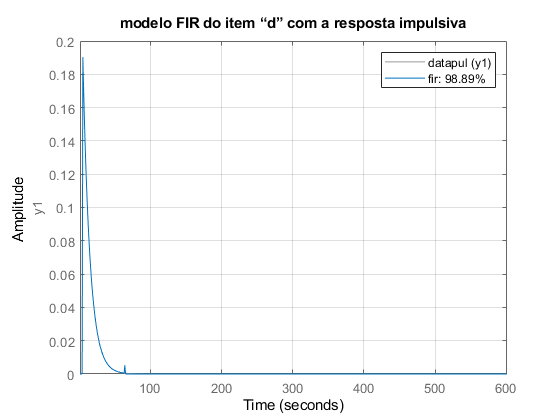

   compare(datapul,fir,Inf); 
   grid; title({'modelo FIR do item “d” com a resposta impulsiva'});

Neste caso podemos afirmar que o modelo FIR responde com fidelidade ao processo porém com um atraso de 1 segundo.

**G.** Estime modelos para as saídas baixa y e alta y afetadas, respectivamente, por perturbações de baixa e alta intensidade e ruído de medição, empregando os dados medidos no  item “c”, utilizando estruturas FIR, ARX, ARMAX, OE e BJ, com as ordens corretas dos  modelos discretizados e com uma única entrada u. Compare os valores estimados dos  parâmetros com seus valores reais dados pela função de transferência discreta do  processo. Realize predições infinitos passos à frente e compare a resposta dos modelos  obtidos com excitação do tipo degrau de amplitude 0,1 com a resposta limpa do  processo a esse mesmo degrau e com a resposta do modelo obtido com dados limpos. Apresente os índices fit obtidos e teça comentários acerca dos resultados obtidos,  focando nas diferenças observadas quando se gera modelos com sinais limpos e  afetados por perturbações e no desempenho dos modelos obtidos pelas diferentes  estruturas. 

Utilizando saída y2 com perturbações de alta e baixa intensidade temos a seguir os modelos estimados:

**ARX:          **$y{\left(t\right)}=\frac{0,1927\ldotp q^{-4} }{1-0,9122\ldotp q^{-1} }u{\left(t\right)}+\frac{1}{1-0,9122\ldotp q^{-1} }\varepsilon \left(t\right)$

**ARMAX:    **$y{\left(t\right)}=\frac{0,1935\ldotp q^{-4} }{1-0,9146\ldotp q^{-1} }u{\left(t\right)}+\frac{1-0,08404\ldotp q^{-1} }{1-0,9146\ldotp q^{-1} }\varepsilon \left(t\right)$

**OE:            **$y{\left(t\right)}=\frac{0,1872\ldotp q^{-4} }{1-0,9319\ldotp q^{-1} }u{\left(t\right)}+\varepsilon \left(t\right)$

**BJ:             **$y{\left(t\right)}=\frac{0,1934\ldotp q^{-4} }{1-0,9215\ldotp q^{-1} }u{\left(t\right)}+\frac{1-0,05898\ldotp q^{-1} }{1-0,888\ldotp q^{-1} }\varepsilon \left(t\right)$

**FIR:            **$y{\left(t\right)}=0,00052\ldotp q^{-63} \ u{\left(t\right)}+\varepsilon \left(t\right)$ Tendo nb=60.

Podemos verificar que os valores dos parâmetros se aproximam mas não são idênticos aos da função de transferência discretizada do sistema.

    clc;clear;close all;
warning off;
% Variáveis...
    grafico=0;
    linha=1;
    
   %variâncias
    baixa=0.001;
    alta=0.1;
    vari=1e-6;
    
    k=2;
    tau=10;
    Kpert1=1;
    TAUpert1=5;
    theta=3;
    Kpert2=2;
    TAUpert21=5;
    TAUpert22=10;
    
    

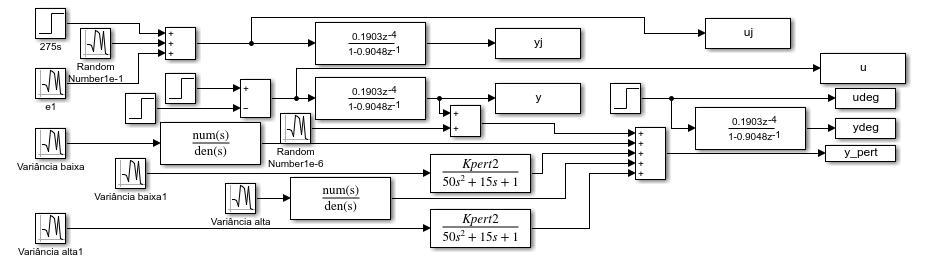

% Rodando simulação do Simulink
    Tsim = 150;
    sim('Lista_2_ex_g');
    
% Sistemas    
    data = iddata(y,u,1);
    data_pert = iddata(y_pert,u,1);
    datadeg = iddata(ydeg,udeg,1);
    

% Estimando modelos com perturbação
    firpert = arx(data_pert,[0 60 4]);
    arxpert = arx(data_pert,[1 1 4]);
    armaxpert = armax(data_pert,[1 1 1 4]);
    oepert = oe(data_pert,[1 1 4]);
    bjpert = bj(data_pert,[1 1 1 1 4]);
    
% Estimando modelos sem perturbação
    fir = arx(data,[0 60 4]);
    arx = arx(data,[1 1 4]);
    armax = armax(data,[1 1 0 4]);
    oe = oe(data,[1 1 4]);
    bj = bj(data,[1 0 0 1 4]);
    
    
% Predições    
    pre_arx = predict(arxpert,datadeg,inf);
    pre_armax = predict(armaxpert,datadeg,inf);
    pre_oe = predict(oepert,datadeg,inf);
    pre_bj = predict(bjpert,datadeg,inf);
    pre_fir = predict(firpert,datadeg,inf);
    

Comparando os modelos gerados pelas saídas com e sem perturbção temos:

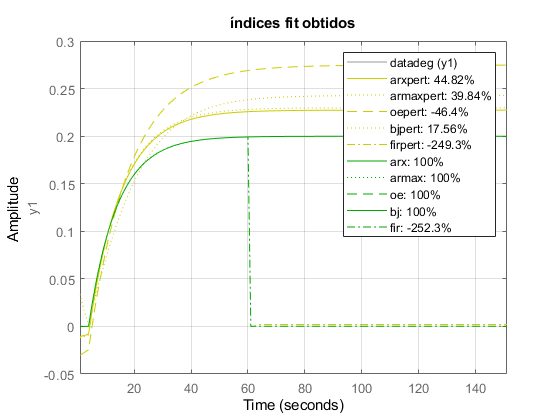

compare(datadeg,arxpert,'y',armaxpert,'y:',oepert,'y--',bjpert,'y:',firpert,'y-.' ...
    ,arx,'g',armax,'g:',oe,'g--',bj,'g',fir,'g-.',Inf); 
grid; title({'índices fit obtidos'});

Podemos observar que os modelos gerados pela resposta com perturbações (amarelo), não são fiéis ao sistema limpo. Já os modelos gerados pela saída limpa (verde), são 100% compatíveis. Com exceção dos modelos FIR, que são compatíveis somente até 60 segundos que é a ordem de nb estipulada anteriormente.

Obs.: no modelo FIR ao alterarmos a ordem do polinômio B (nb) para 70, verificamos que a saída do modelo permanece fiel até os 70 segundos. mostrado a seguir no gráfico azul:

**H.** Apresente e compare o ganho estacionário dos modelos obtidos no item “g” com  perturbação de baixa e alta intensidade com o ganho estacionário do processo.  Comente os resultados obtidos.

Ao comparar o ganho estacionário dos modelos obtidos com a saída perturbada, vemos que todos estão bastante diferentes, assim podemos concluir que seriam modelos inviáveis.

**I.** Como a perturbação  1 v afeta mais a saída que  2 v , suponha que no sinal  1 e , que gera  essa perturbação, seja instalado um medidor, que é afetado por ruído de medição com  distribui-ção gaussiana, com média nula e variância 1e-6. Repita o item “g”, mas  considerando como entradas do modelo tanto o sinal u como a perturbação medida  1 e .  Apresente os modelos obtidos para  baixa y e alta y e compare o desempenho dos  modelos obtidos neste item com duas entradas com aquele obtido no item “g” com uma  só entrada, através do comando “compare, exibindo os índices fit obtidos. Qual modelo  ficou melhor para cada estrutura testada: com 1 ou 2 entradas? Por que? 

    clc;clear;close all;
warning off;
% Variáveis...
    grafico=0;
    linha=1;
    
   %variâncias
    baixa=0.001;
    alta=0.1;
    vari=1e-6;
    
    k=2;
    tau=10;
    Kpert1=1;
    TAUpert1=5;
    theta=3;
    Kpert2=2;
    TAUpert21=5;
    TAUpert22=10;
    

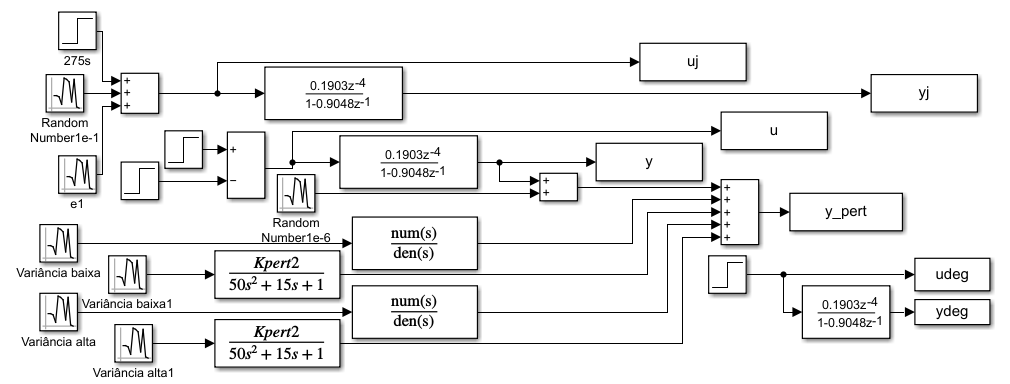

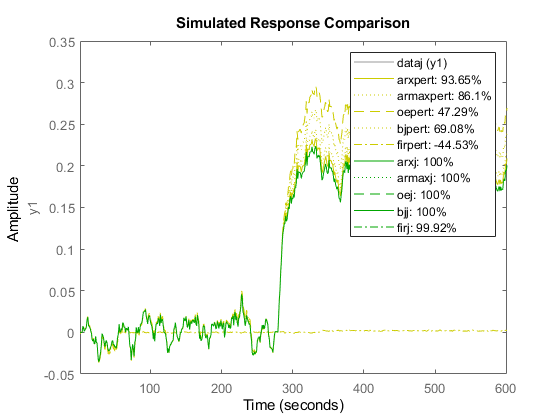

    
% Rodando simulação do Simulink
    Tsim = 600;
    sim('Lista_2_ex_i');
    
% Sistemas    
    data = iddata(y,u,1);
    datadeg = iddata(ydeg,udeg,1);
    dataj = iddata(yj,uj,1);
    data_pert = iddata(y_pert,u,1);
   

% Estimando modelos com perturbação medida
    firj = arx(dataj,[0 60 4]);
    arxj = arx(dataj,[1 1 4]);
    armaxj = armax(dataj,[1 1 1 4]);
    oej = oe(dataj,[1 1 4]);
    bjj = bj(dataj,[1 1 1 1 4]);
 
% Estimando modelos com perturbação
    firpert = arx(data_pert,[0 60 4]);
    arxpert = arx(data_pert,[1 1 4]);
    armaxpert = armax(data_pert,[1 1 1 4]);
    oepert = oe(data_pert,[1 1 4]);
    bjpert = bj(data_pert,[1 1 1 1 4]);
    
% Estimando modelos sem perturbação
    fir = arx(data,[0 60 4]);
    arx = arx(data,[1 1 4]);
    armax = armax(data,[1 1 0 4]);
    oe = oe(data,[1 1 4]);
    bj = bj(data,[1 0 0 1 4]);
    
compare(dataj,arxpert,'y',armaxpert,'y:',oepert,'y--',bjpert,'y:',firpert,'y-.' ...
        ,arxj,'g',armaxj,'g:',oej,'g--',bjj,'g',firj,'g-.',Inf)

**J.** Apresente e compare o ganho estacionário dos modelos obtidos com uma perturbação  medida, conforme item “i”, com o ganho estacionário do processo e com o ganho dos  modelos gerados com apenas uma entrada medida, conforme o item “g”, em que não se  mediu nenhuma perturbação. Comente os resultados obtidos.

- Os modelos gerados com duas entradas no exercício I (verde) correspondem exatamente ao processo. Já os modelos obtidos com uma entrada sem perturbações medidas (amarelo), possuem ganhos elevados comparados ao processo livre de perturbações.

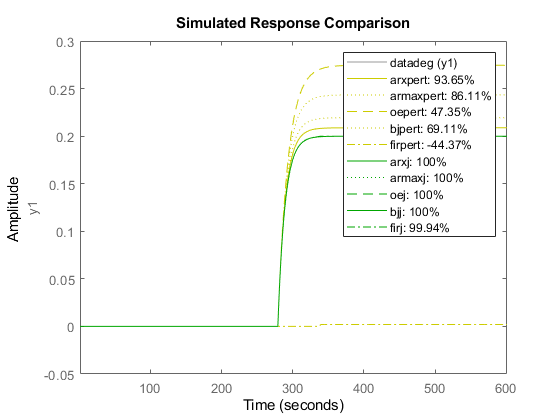

compare(datadeg,arxpert,'y',armaxpert,'y:',oepert,'y--',bjpert,'y:',firpert,'y-.' ...
          ,arxj,'g',armaxj,'g:',oej,'g--',bjj,'g',firj,'g-.',Inf)